parpool("threads");% なしで54sec,
% delete(gcp('nocreate'));

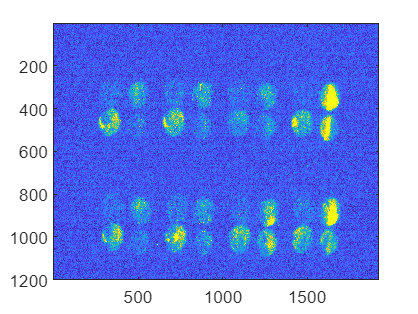

tic % タイマー取得
TIFImagePath = 'G:\My Drive\X-ray\Data\TIF\231216\shot016.tif';

% 生画像の取得
RawTIFImage = imread(TIFImagePath);

% 非線形フィルターをかける
imagesc(RawTIFImage);clim([49,60]);

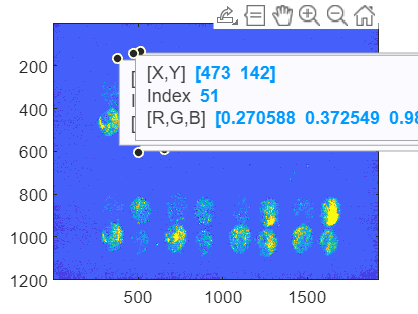

patch = RawTIFImage(1:200,1:200);
patchSq = patch.^2;
edist = sqrt(sum(patchSq,3));
patchSigma = sqrt(var(edist(:)));
[Filtered1TIFImage,estDos] = imnlmfilt(RawTIFImage,'SearchWindowSize',91,'ComparisonWindowSize',13,'DegreeOfSmoothing',patchSigma*0.625);
imagesc(Filtered1TIFImage);clim([49,60]);

Filtered2TIFImage = imgaussfilt(Filtered1TIFImage);
% imagesc(Filtered2TIFImage);clim([49,60]);
toc % タイマー回収

Elapsed time is 153.368496 seconds.


% 度数分布
num = numel(RawTIFImage);
RawEE = reshape(RawTIFImage,[1,num]);
plot((1:num),RawEE);hold on;
Filtered1EE = reshape(Filtered1TIFImage,[1,num]);
plot((1:num),Filtered1EE);
% Filtered2EE = reshape(Filtered2TIFImage,[1,num]);
% plot((1:num),Filtered2EE);
hold off;